# ロジスティック関数(シグモイド関数)を図示する

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

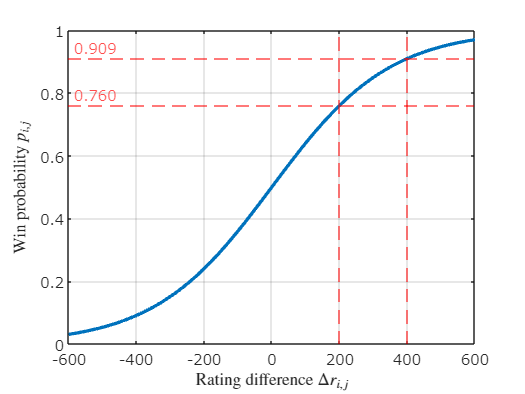

clear;clc;close all
dr=-600:10:600;
p=1./(1+10.^(-dr/400));
figure
plot(dr,p,'LineWidth',2);
grid on;set(gca,'fontname','メイリオ');
xlabel('Rating difference $\Delta r_{i,j}$','Interpreter','latex');
ylabel('Win probability $p_{i,j}$','Interpreter','latex');

xVals=[200; 400];
xline(xVals,'r--');
hold on;
for n1=1:size(xVals,1)
    yline(1./(1+10^(-xVals(n1)/400)),'r--',num2str(1./(1+10^(-xVals(n1)/400)),'%1.3f'), ...
        'LabelHorizontalAlignment','left','FontName','メイリオ')
end

exportgraphics(gcf,'fig_sigmoidFunc.pdf');